## Load

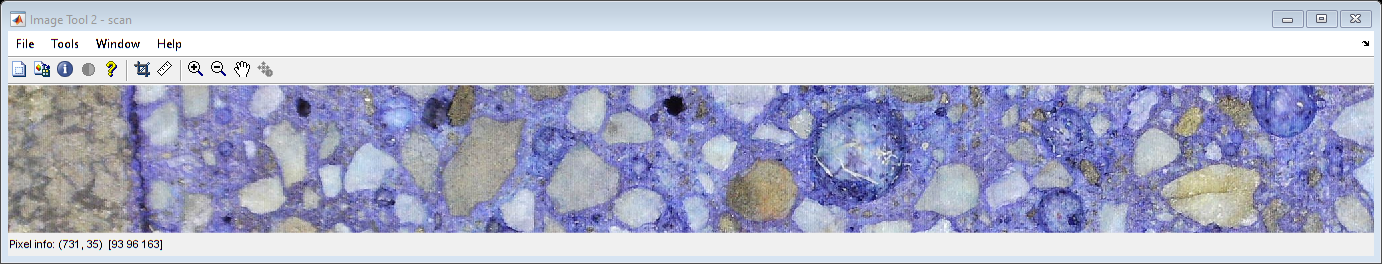

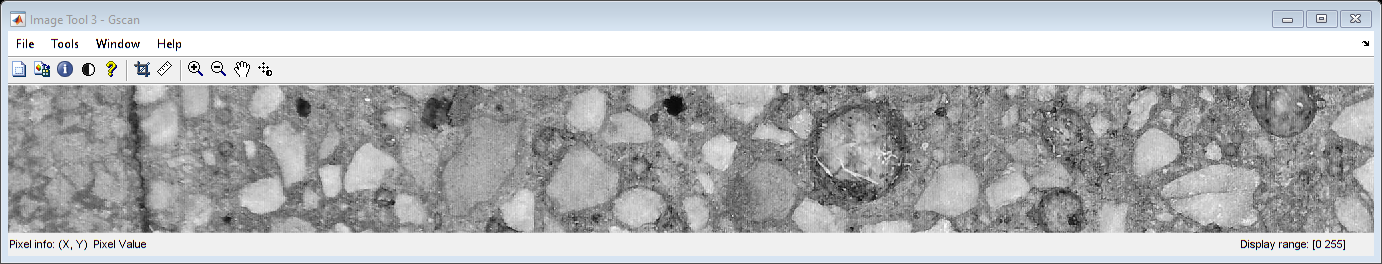

close all
scan = imread('tests/test2/scan0/x00y03_zoom.jpeg');
Gscan = rgb2gray(scan);
% scan5_zoom = imread('tests/test2/scan0/x00y05_zoom.jpeg');
figure
set(gcf,'Visible','on')
imtool(scan)
imtool(Gscan)

## Edge mask test

figure(1)

Gscan_f1 = imfilter(Gscan,ones(3)/5)

Gscan_f1 = 221×2048 uint8 matrix
   100   149   150   158   177   199   213   204   192   181   179   176   179   186   193   201   198   183   167   155   146   145   154   168   176   183   195   203   209   214   215   215   213   214   219   227   233   232   230   228   237   248   255   255   253   245   238   229   224   217
   151   226   227   237   255   255   255   255   255   255   255   255   255   255   255   255   255   255   247   230   216   212   222   240   251   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   155   230   232   241   255   255   255   255   255   255   255   255   255   255   255   255   255   255   243   226   210   203   209   221   230   241   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   164   242   246   255   255   255   255   255   255   255   2

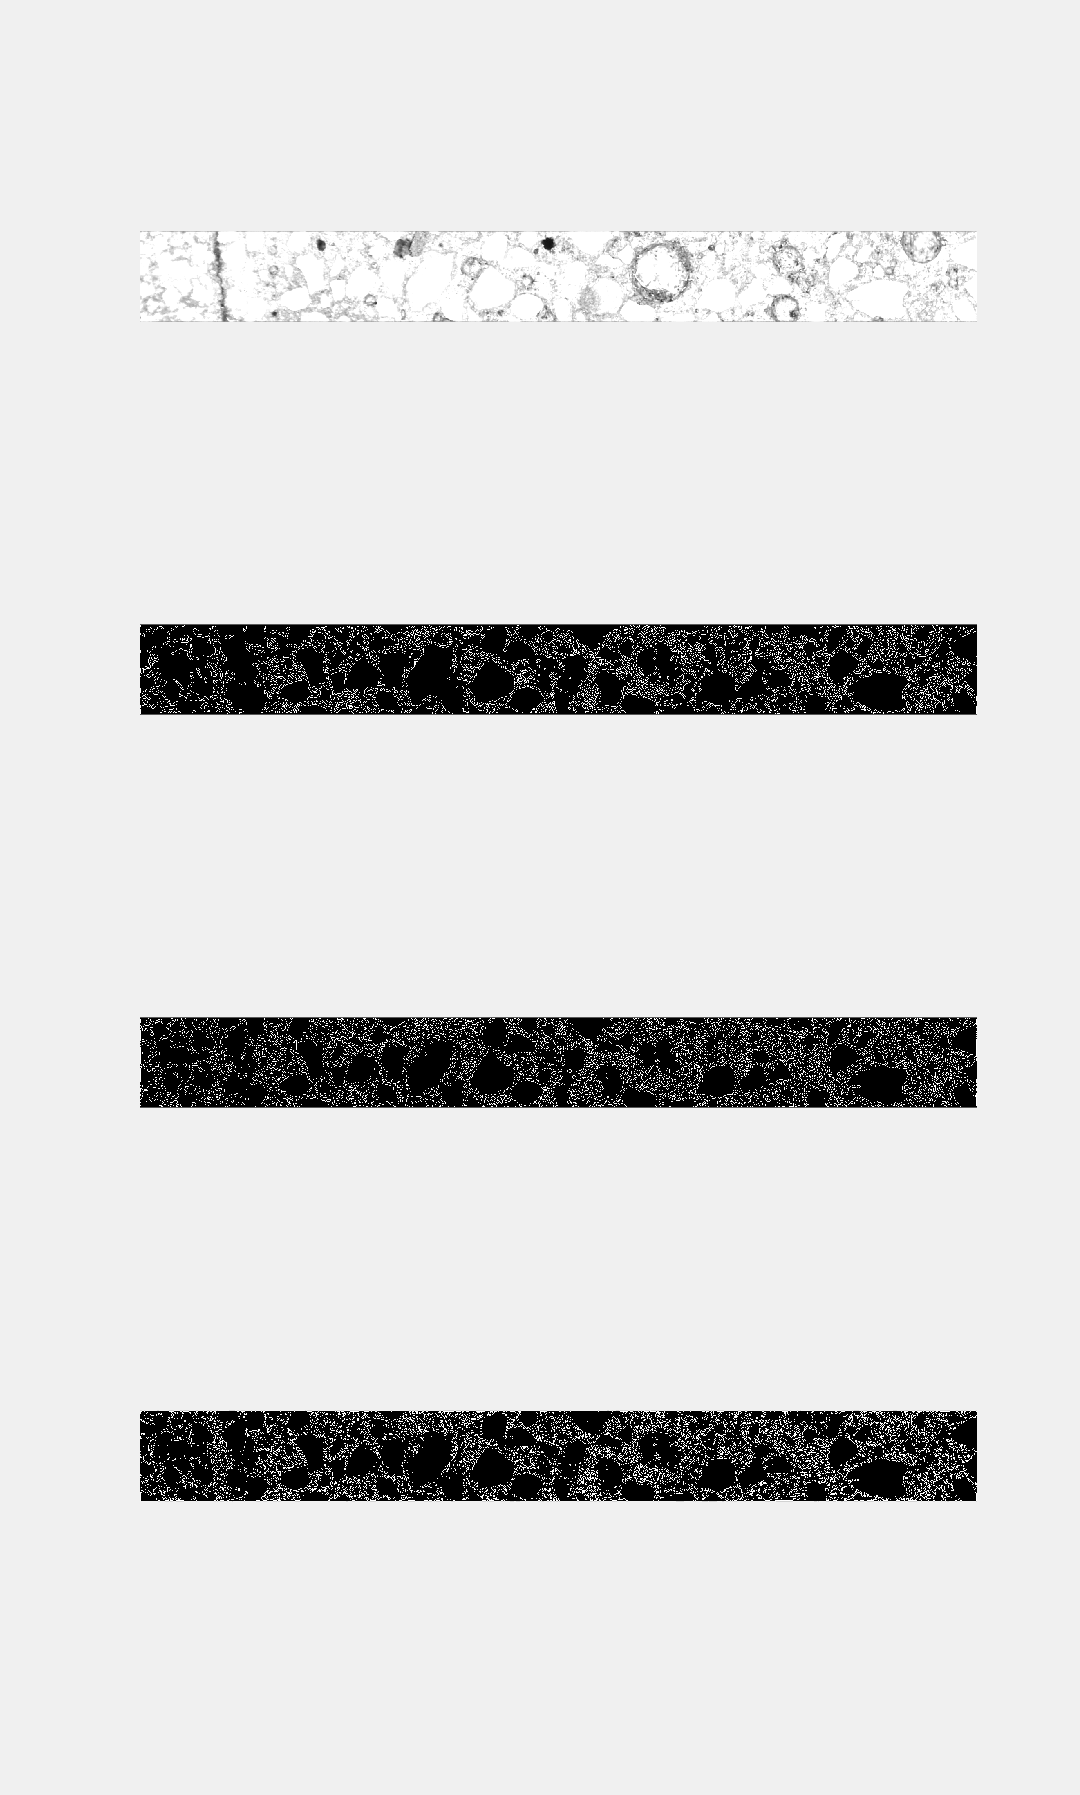

subplot(4, 1, 1);
imshow(Gscan_f1);

BW = edge(Gscan_f1,"canny",0.1);
subplot(4, 1, 2), imshow(BW);

BW = edge(Gscan_f1,"zerocross",0.001);
subplot(4, 1, 3), imshow(BW);

% BW = edge(Gscan_f1,"prewitt",0.02);
% subplot(4, 1, 4), imshow(BW);

BW = edge(Gscan_f1,"sobel",0.009);
subplot(4, 1, 4), imshow(BW);